%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [10, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["file", "date", "latitude", "longitude", "ocean", "profiler_type", "institution", "parameters", "parameter_data_mode", "date_update"];
opts.VariableTypes = ["string", "double", "double", "double", "string", "double", "string", "string", "string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["file", "ocean", "institution", "parameters", "parameter_data_mode"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["file", "ocean", "institution", "parameters", "parameter_data_mode"], "EmptyFieldRule", "auto");

% Import the data
argoDat = readtable("argo_synthetic-profile_index.txt", opts)

argoDat = 304767×10 table
                      file                         date       latitude    longitude    ocean    profiler_type    institution         parameters          parameter_data_mode    date_update
    ________________________________________    __________    ________    _________    _____    _____________    ___________    _____________________    ___________________    ___________

    "aoml/1900722/profiles/SD1900722_001.nc"    2.0061e+13    -40.316      73.389       "I"          846            "AO"        "PRES TEMP PSAL DOXY"          "DDDD"           2.0221e+13 
    "aoml/1900722/profiles/SD1900722_002.nc"    2.0061e+13     -40.39

argoDat.date = num2str(argoDat.date);

% Convert string to datetime
argoDat.datetime = datetime(argoDat.date, 'InputFormat', 'yyyyMMddHHmmss'); 

%% Clear temporary variables
clear opts

**Question 1: How many unique profiling floats (i.e. unique WMO IDs) that measure the DOXY parameter have been deployed? How about PH_IN_SITU_TOTAL? NITRATE? And finally, floats with both DOXY and NITRATE? **

**ANSWER: **

Number of DOXY floats deployed: 1985

Number of PH_IN_SITU_TOTAL floats deployed: 568

Number of NITRATE floats deployed: 653

Number of DOXY with NITRATE floats deployed: 652

% Splite the file data by '/' and isolate the 7-digit WMO_ID
fileSplit = split(argoDat.file,'/');

% Create a seperate column in the data table with WMO_ID as a double
argoDat.WMO_ID=str2double(fileSplit(:,2));

% Call all rows of data that contain "DOXY"
DOXY = unique(argoDat.WMO_ID(contains(argoDat.parameters, "DOXY")==1));

% Call all rows of data that contain "PH_IN_SITU_TOTAL"
PH = unique(argoDat.WMO_ID(contains(argoDat.parameters, "PH_IN_SITU_TOTAL")==1));

% Call all rows of data that contain "NITRATE"
NITRATE = unique(argoDat.WMO_ID(contains(argoDat.parameters, "NITRATE")==1));

% Call all rows of data that contain "DOXY" and "NITRATE"
DOXY_NITRATE = unique(argoDat.WMO_ID(contains(argoDat.parameters, "NITRATE")==1 ...
    & contains(argoDat.parameters, "DOXY")==1));

% Print the number of unique floats for each parameter
fprintf('The number of DOXY floats deployed is %d\n', length(DOXY))

The number of DOXY floats deployed is 1985


fprintf('The number of PH IN SITU TOTAL floats deployed is %d\n', length(PH))

The number of PH IN SITU TOTAL floats deployed is 568


fprintf('The number of NITRATE floats is deployed %d\n', length(NITRATE))

The number of NITRATE floats is deployed 653


fprintf('The number of DOXY with NITRATE floats deployed is %d\n', length(DOXY_NITRATE))

The number of DOXY with NITRATE floats deployed is 652


**QUESTION 2: Make a plot of the number of profiles of DOXY (y axis) versus year (x axis) between 2000 and 2023. Do the same for NITRATE, PH_IN_SITU_TOTAL, CHLA, and BBP700.**

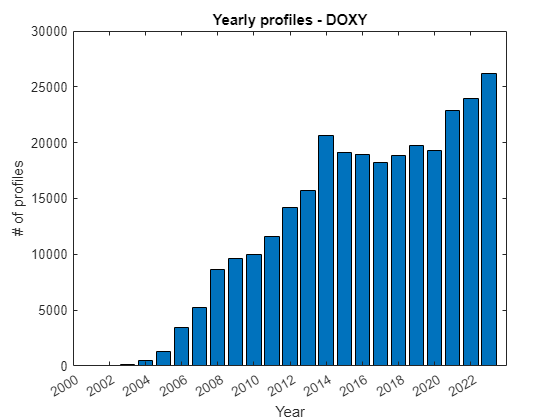

x_values = 2000:2:2023;
% Plot for DOXY
[profiles_DOXY, year_DOXY] = groupcounts(year(argoDat.datetime(contains(argoDat.parameters, "DOXY")==1)));
bar(year_DOXY(1:end-2),profiles_DOXY(1:end-2))
title("Yearly profiles - DOXY")
ylabel("# of profiles")
xlabel("Year")
set(gca,'xlim',[2000 2024])
xticks(x_values);
ax = gca;
ax.YAxis.Exponent = 0;

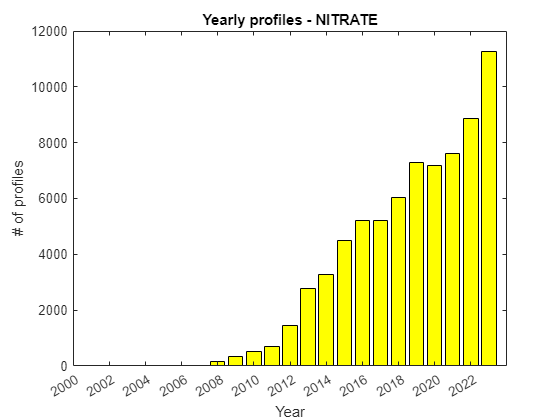


% Plot for NITRATE
[profiles_NITRATE, year_NITRATE] = groupcounts(year(argoDat.datetime(contains(argoDat.parameters, "NITRATE")==1)));
bar(year_NITRATE(1:end-2),profiles_NITRATE(1:end-2),"yellow")
set(gca,'xlim',[2000 2024])
xticks(x_values);
title("Yearly profiles - NITRATE")
ylabel("# of profiles")
xlabel("Year")

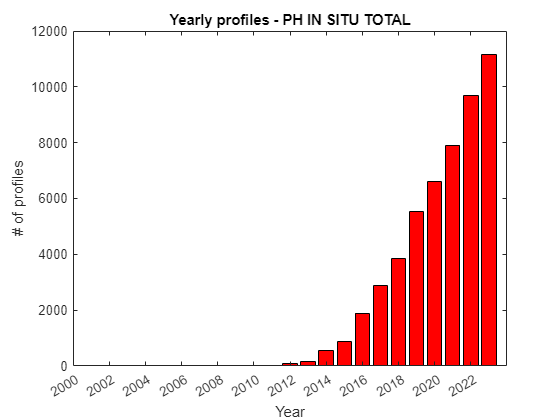


% Plot for PH_IN_SITU_TOTAL
[profiles_PH, year_PH] = groupcounts(year(argoDat.datetime(contains(argoDat.parameters, "PH_IN_SITU_TOTAL")==1)));
bar(year_PH(1:end-2),profiles_PH(1:end-2),"red")
set(gca,'xlim',[2000 2024])
xticks(x_values);
title("Yearly profiles - PH IN SITU TOTAL")
ylabel("# of profiles")
xlabel("Year")

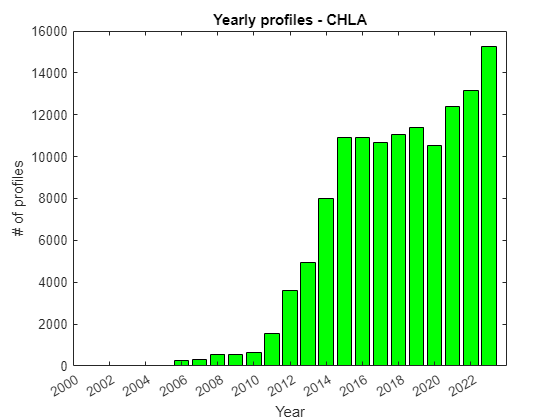


% Plot for CHLA
[profiles_CHLA, year_CHLA] = groupcounts(year(argoDat.datetime(contains(argoDat.parameters, "CHLA")==1)));
bar(year_CHLA(1:end-2),profiles_CHLA(1:end-2),"green")
set(gca,'xlim',[2000 2024])
xticks(x_values);
title("Yearly profiles - CHLA")
ylabel("# of profiles")
xlabel("Year")

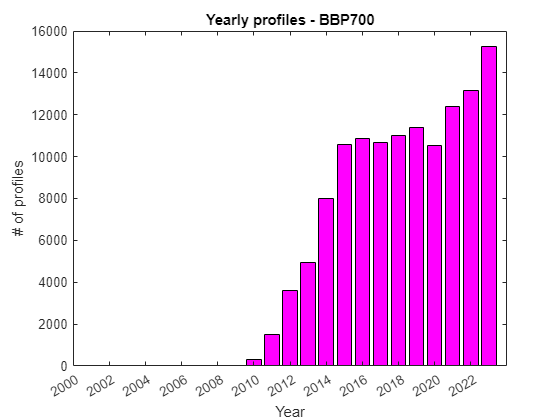


% Plot for BBP700
[profiles_BBP700, year_BBP700] = groupcounts(year(argoDat.datetime(contains(argoDat.parameters, "BBP700")==1)));
bar(year_BBP700(1:end-2),profiles_BBP700(1:end-2),"magenta")
set(gca,'xlim',[2000 2024])
xticks(x_values);
title("Yearly profiles - BBP700")
ylabel("# of profiles")
xlabel("Year")

**QUESTION 3: Using information from the argo_synthetic-profile_index.txt file, make a plot or map regarding a distribution or statistic that you find interesting. This is meant to be an open ended question. **

**ANSWER: **I found PH_IN_SITU_TOTAL to be one of the most interesting parameters because it's a relatively recent (but widely used) inclusion on the floats. I've plotted a map of PH_IN_SITU_TOTAL profiles colored by the year of deployment in order to show spatial distribution with time. While the current spatial coverage of PH is broad across all latitudes, there is an increasing number of Northern latitude deployments with time. Until 2020, most deployments with PH appear to be concentrated in the Southern Ocean. After 2020, the distribution covers latitudes as north as 75 degrees, resolving PH near the arctic circle. Likewise, the longitudinal distribution is extensive, covering previously unsampled regions such as the equatorial Pacific, the Atlantic, and in the Indian ocean beyond the year 2022.

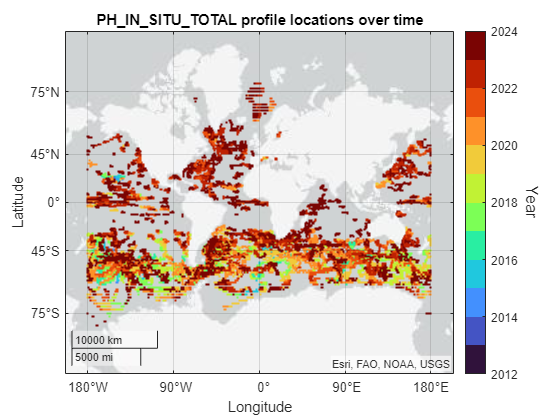

param = "PH_IN_SITU_TOTAL";
argoLat = round(argoDat.latitude(contains(argoDat.parameters, param)==1), ...
    0,TieBreaker="fromzero");
argoLon = round(argoDat.longitude(contains(argoDat.parameters, param)==1), ...
    0,TieBreaker="fromzero");
argoDate = year(argoDat.datetime(contains(argoDat.parameters, param)==1));

figure;

geoscatter(argoLat,argoLon,3,argoDate,"filled")
geolimits([-90 90],[-180 180]);
title(param + " profile locations over time", 'Interpreter', 'none');

tickVals=min(argoDate):1:max(argoDate);
cmap = turbo(length(tickVals)-1);
colormap(cmap);
cbar = colorbar;
cbar.Label.String = "Year";
cbar.Label.FontSize = 12;
cbar.Label.Rotation=-90;